# Adaptive control for positioning systems

## Adaptive control strategy: ***Self tuning controller***

clear; clc;

**Nominal model initializations**

sqareWaveGen = @(t, T)((t - T*floor(t/T)) < T/2);
Kf0 = 3;
Tf0 = 5;
wn = 1; % closed loop performance parameter
zeta = 1; % closed loop performance parameter
Te = 0.1;
T = 300*Te;
t = 0:Te:5*T;
u = sqareWaveGen(t, T) - 0.5;
%u = sin(t);

**Discrete models instantiation**

Hf = tf(Kf0, [Tf0 1 0]);
Hfd = c2d(Hf, Te, 'zoh');
[num, den] = tfdata(Hfd, 'v');
system = LinearDiscreteModel(num(2:end), den, 0);
[num, den] = getDiscreteCompensator(den(2), num(2), Te, wn, zeta);
controller = LinearDiscreteModel(num, den, 0);

**Numeric initialization**

error = zeros(length(u), 1);
output = zeros(length(u), 1);
command = zeros(length(u), 1);
error(1) = u(1);
squaredError = zeros(length(u), 1);

**AAP Initialization**

% model structure parameters
na = 2;
nb = 1;
nd = 1;
windowSize = 200; % observation vector and measurements size
wIdx = 1;
window = zeros(na + nb + 1, 1); 
inputBuffer = zeros(nd, 1);
outputBuffer = zeros(1, 1);
wY = zeros(windowSize, 1); % measurements
phi = zeros(nb + na + 1, windowSize); % observation vector

% optimizer utility functions
evalCost = @(theta, phi, y)((1/2)*sum((y - theta'*phi).^2));
alpha = 1; % optimizer step
beta = 1.1; % bactracking step increment
alphaUpperThreshold = 10000; % step upper boundary
alphaBottomTreshold = 0.0000001; % step bottom boundary

% paramters vector initialization
[num, den] = tfdata(Hfd, 'v');
theta = [num(2:end)'; den(2:end)'];
theta = [theta theta];

% non-zero intial conditions avoidance
timeUnitsToWait = max(nb + nd, na);
timeUnitsWaited = 0;
isReady = false;

**Variation timing**

f = 1;
changeTime = zeros(2, 1);

## Numeric Simulation

for i = 1:length(u)-1
    error(i) = u(i) - output(i);
    [controller, command(i)] = controller.forward(error(i));
    [system, output(i + 1)] = system.forward(command(i));
          
    if i == floor(length(u)/5) || i == floor(length(u)/2) 
        %Kf = normrnd(Kf0, 2);
        Kf0 = Kf0 - 1.4;
        Tf0 = Tf0 - 2;
        %Tf = normrnd(Tf0, 1);
        Hf = tf(Kf0, [Tf0 1 0]);
        Hfd = c2d(Hf, Te, 'zoh');
        [num, den] = tfdata(Hfd, 'v');
        system = system.changeParameters(num(2:end), den);
        changeTime(f) = t(i);
        f = f + 1;
    end
    
    % observation vector update mechanims
    if nd >= 1
        window(1) = inputBuffer(1);
    else
        window(1) = command(i);
    end
    for j = 2:nb+1
        if wIdx - 1 >= 1
            window(j) = phi(j - 1, wIdx - 1);
        end
    end
    if nd > 1 
        inputBuffer(1:end-1) = inputBuffer(2:end);
        inputBuffer(end) = command(i);
    else
        inputBuffer = command(i);
    end
    
    window(nb + 2) = -outputBuffer;
    for k = nb+3:nb+1+na
        if wIdx - 1 >= 1
            window(k) = phi(k - 1, wIdx - 1);
        end
    end
    outputBuffer = output(i);
    
    if wIdx <= windowSize
        phi(:, wIdx) = window;
        wY(wIdx) = output(i);
        idx = wIdx;
        wIdx = wIdx + 1;
    else
        phi = [phi(:, 2:end) window];
        wY = [wY(2:end); output(i)];
    end
    
    if isReady == false && timeUnitsWaited >= timeUnitsToWait
        isReady = true;
        phi = [phi(:, timeUnitsToWait+1:end) zeros(nb + na + 1, timeUnitsToWait)];
        wY = [wY(timeUnitsToWait+1:end); zeros(timeUnitsToWait, 1)];
        wIdx = 2;
        idx = 1; 
    end
    
    squaredError(i) = evalCost(theta(:, 1), phi(:, 1:idx), wY(1:idx)');
    if isReady == false
        timeUnitsWaited = timeUnitsWaited + 1;
    else
         % AAP
        theta = AAP(theta, phi(:, 1:idx), wY(1:idx), alpha, beta, alphaUpperThreshold, alphaBottomTreshold);
        
        % auto-tuning the controller
        [num, den] = getDiscreteCompensator(theta(3, 2), theta(1, 2), Te, wn, zeta);
        controller = controller.changeParameters(num, den);
    end
end

## Results

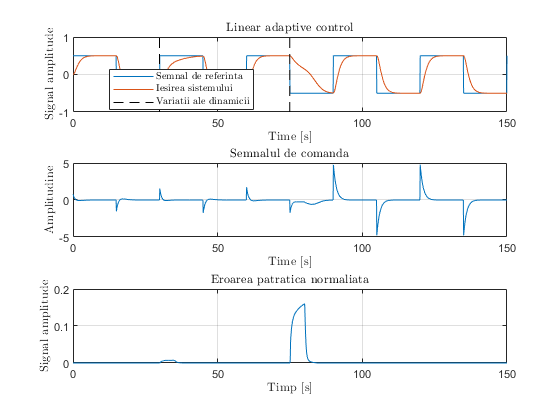

figure,
subplot(3, 1, 1)
plot(t, u);
hold on;
plot(t, output); grid;
xline = -1:0.1:1;
yline = changeTime.*ones(length(xline), 2)';
plot(yline, xline, "--", "Color", "Black");
title("Linear adaptive control", "Interpreter", "Latex");
xlabel("Time [s]", "Interpreter", "latex");
ylabel("Signal amplitude", "Interpreter", "latex");
legend("Semnal de referinta", "Iesirea sistemului", "Variatii ale dinamicii", ...
    "Interpreter", "Latex", "Location","best");

subplot(3, 1, 2)
plot(t, command); grid;
title("Semnalul de comanda", "Interpreter", "Latex");
xlabel("Time [s]", "Interpreter", "latex");
ylabel("Amplitudine", "Interpreter", "latex");

subplot(3, 1, 3)
plot(t, squaredError/norm(squaredError)); grid;
title("Eroarea patratica normaliata", "Interpreter", "Latex");
xlabel("Timp [s]", "Interpreter", "latex");
ylabel("Signal amplitude", "Interpreter", "latex");

function [num, den] = getDiscreteCompensator(a1, b1, Te, Wn, zeta)
    Tf = -Te/(log(-1 - a1));
    Kf = b1/(Tf*(exp(-Te/Tf) - 1) + Te);
    ca0 = 1 + 1/(zeta*Wn*Te);
    ca1 = 1 - 1/(zeta*Wn*Te);
    cb0 = 1 + 2*Tf/Te;
    cb1 = 1 - 2*Tf/Te;
    num = (Wn/(2*Kf*zeta))*[cb0 cb1];
    den = [ca0 ca1];
    num = num/den(1);
    den = den/den(1);
end